# Syllable splitting - br177yw112, syllable 'd' 

## DAY 86

#### Plot distributions of pitch and syllable duration

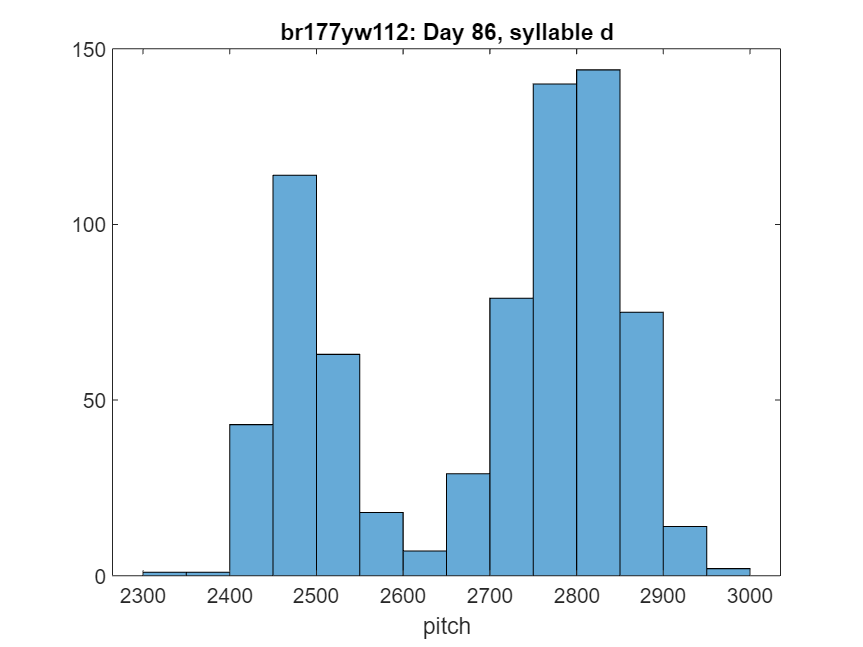

birdID = 'br177yw112';
neuronID = 'day86';
syl_or_seq = 'd';
neural_channel = 6;
pre_onset_time_s = 0.2;
filelist = 'batch_passed_ch6_clust2.txt';

% [neuralcase] = compile_case(birdID,neuronID,syl_or_seq,neural_channel,pre_onset_time_s,filelist)

load('J:\MINI DATASET\br177yw112_day86_ch6\compile_cases\br177yw112_d_day86_ch6_premotor_200ms_spiketimes_acoustics_2024-02-14.mat')
f1 = neuralcase.weighted_avg_pitch;
durs = neuralcase.syl_ons_offs(:,2) - neuralcase.syl_ons_offs(:,1);
recname = neuralcase.recfilename;

figure;histogram(f1); title('br177yw112: Day 86, syllable d'); xlabel('pitch')

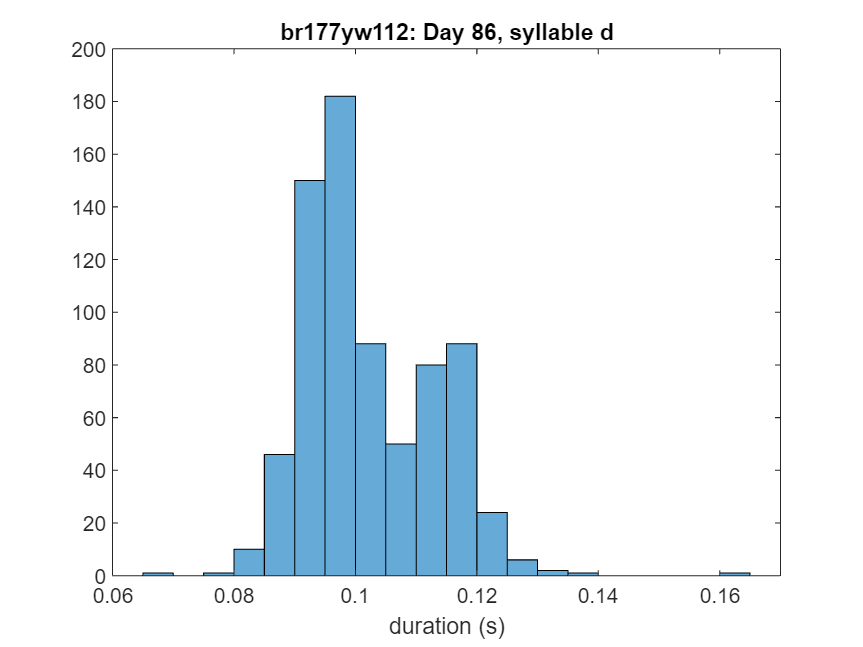

figure;histogram(durs); title('br177yw112: Day 86, syllable d'); xlabel('duration (s)')

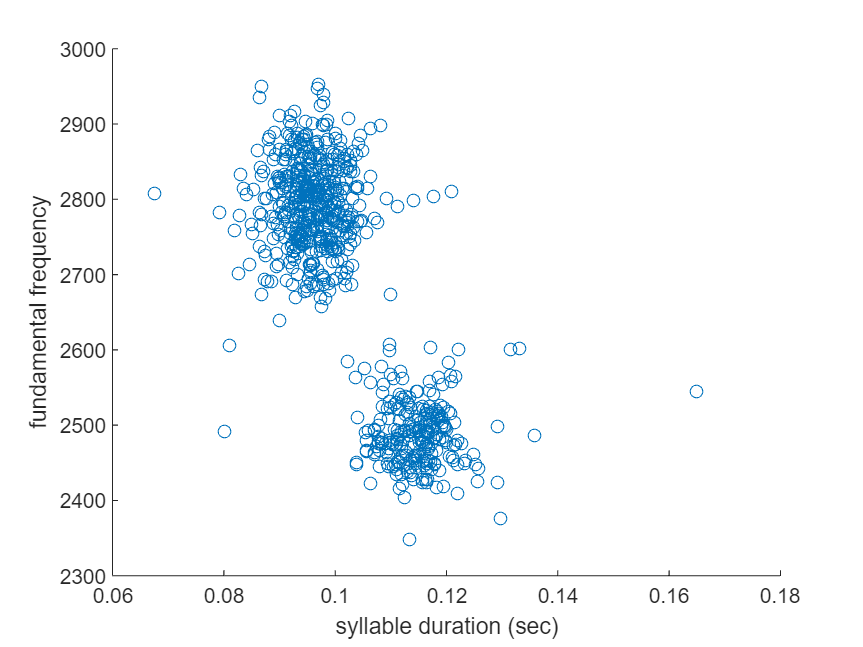


figure;scatter(durs,f1)
xlabel('syllable duration (sec)')
ylabel('fundamental frequency')

% find shortened syllable trials
short = durs > 0.14;
short_d_files = recname(short);
short_onsets = neuralcase.syl_ons_offs(short,1:2);

Cluster using k-means, assume 2 clusters

%create matrix of k-means
acoustics = table(f1, durs);
X(:,1) = f1; 
X(:,2) = durs;
rng('default')


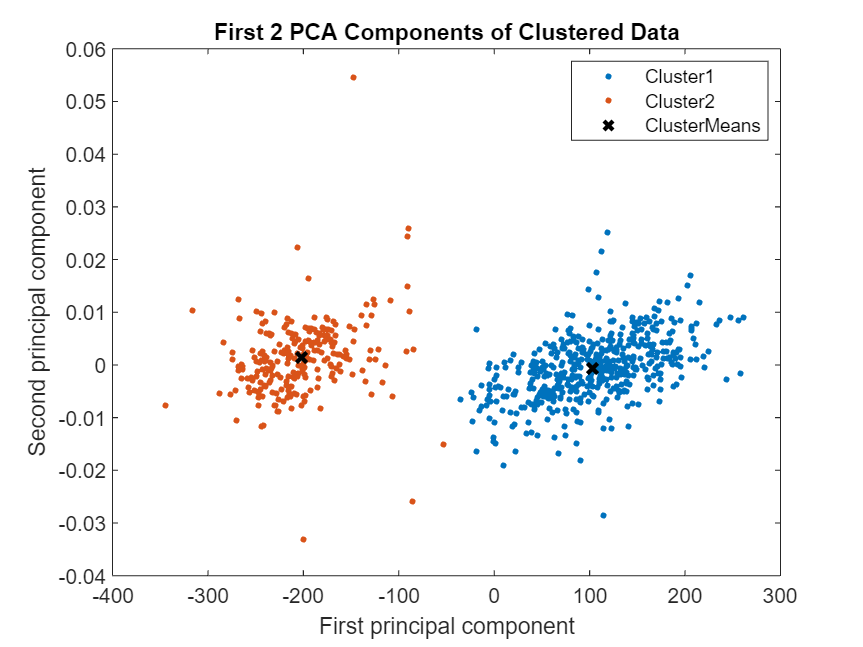

% Perform k-means clustering using specified number of clusters (K value)
K = 2;
[clusterIndices,centroids] = kmeans(X,K);

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score] = pca(X);
clusterMeans = grpstats(score,clusterIndices,"mean");
h2 = gscatter(score(:,1),score(:,2),clusterIndices);
for i = 1:numel(h2)
    h2(i).DisplayName = strcat("Cluster",h2(i).DisplayName);
end
clear h2 i score
hold on
h2 = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h2.DisplayName = "ClusterMeans";
clear h2 clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");

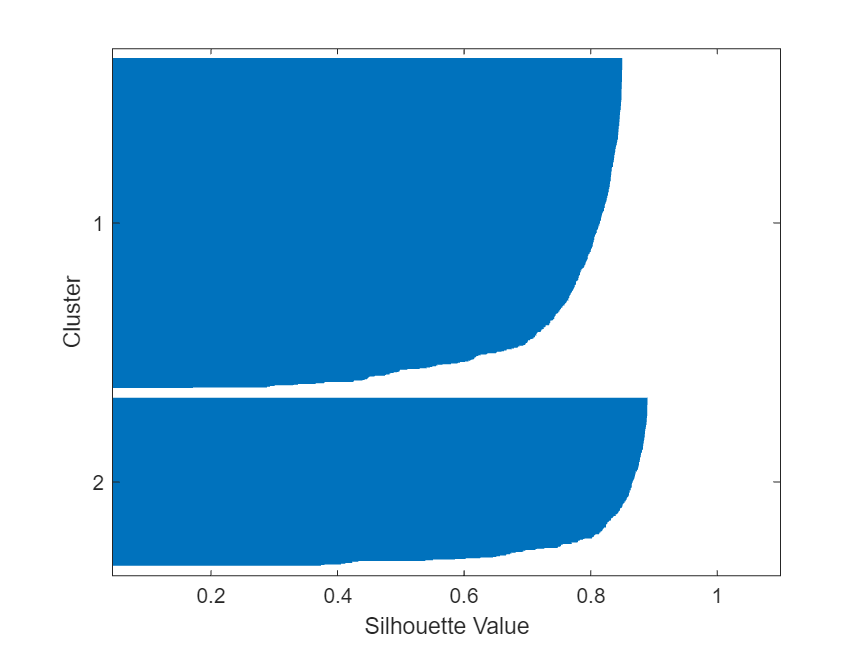


% Matrix plot
figure
selectedCols = sort([2,1]);
[~,ax] = gplotmatrix(X(:,selectedCols),[],clusterIndices,[],[],[],[],"grpbars");
title("Comparison of Columns in Clustered Data");
clear K
clusterMeans = grpstats(X,clusterIndices,"mean");
hold(ax,"on");
for i = 1 : size(selectedCols,2)
  for j = 1 : size(selectedCols,2)
      if i ~= j  
          scatter(ax(j,i),clusterMeans(:,selectedCols(i)),clusterMeans(:,selectedCols(j)), ...
            50,"kx","LineWidth",1.5,"DisplayName","ClusterMeans");
          xlabel(ax(size(selectedCols,2),i),("Column" + selectedCols(i)));
          ylabel(ax(i,1),("Column" + selectedCols(i)));
      end
   end
end
clear ax clusterMeans i j selectedCols

% silhouette plot to measure how close each point in one cluster is to points in the neighboring clusters
[silh3,h] = silhouette(X,clusterIndices,'cityblock');
xlabel('Silhouette Value')
ylabel('Cluster')


% save k-means results
filename = 'br177yw112_d_day86_ch6_premotor_200ms_spiketimes_acoustics_2024-02-14.mat';
save(filename, 'clusterIndices', 'centroids','acoustics','silh3', '-append')

Error using save
Unable to write file br177yw112_d_day86_ch6_premotor_200ms_spiketimes_acoustics_2024-02-14.mat: No such file or directory.

Calculate fano factor with combined and split 'd' distributions

% all 'd', no split
allspikes = neuralcase.spiketrains; 
ntrials = length(allspikes);
onsets = neuralcase.syl_ons_offs(:,1);

preonset = 0.01;
postonset = 0.03;
motor_window = preonset + postonset;


motorWinOn = onsets - preonset;
motorWinOff = onsets + postonset; 
 % for each trial in curr case, caculate spike count, mean isi & mean ifr 
    for j = 1:ntrials
        spk = allspikes{j};
        spks_wn{j,1} = spk(spk >= motorWinOn(j) & spk <= motorWinOff(j));
        n_spikes(j,1) = length(spks_wn{j}); %spk count

        if n_spikes(j,1) > 1
            mean_isi_case(j) = mean(diff(spks_wn{j,1})); % mean isi
            mean_ifr_case(j) = 1/mean_isi_case(j); % mean ifr
        end
    end


ff = var(n_spikes)/ mean(n_spikes)

ff = 3.6257

split 'd'

% split d1, d2 according to clusters
d1 = allspikes(clusterIndices==1); 
d2 = allspikes(clusterIndices==2);
ntrials_d1 = length(d1);
ntrials_d2 = length(d2);
onsets_d1 = onsets(clusterIndices ==1);
onsets_d2 = onsets(clusterIndices ==2);

preonset = 0.01;
postonset = 0.03;
motor_window = preonset + postonset;


motorWinOn_d1 = onsets_d1 - preonset;
motorWinOff_d1 = onsets_d1 + postonset; 
motorWinOn_d2 = onsets_d2 - preonset;
motorWinOff_d2 = onsets_d2 + postonset; 

clearvars n_spikes spks spks_wn 
 % for each trial in curr case, caculate spike count, mean isi & mean ifr 
    for j = 1:ntrials_d1
        spk = d1{j};
        spks_wn{j,1} = spk(spk >= motorWinOn_d1(j) & spk <= motorWinOff_d1(j));
        n_spikes(j,1) = length(spks_wn{j}); %spk count

        if n_spikes(j,1) > 1
            mean_isi_case(j) = mean(diff(spks_wn{j,1})); % mean isi
            mean_ifr_case(j) = 1/mean_isi_case(j); % mean ifr
        end
    end

ff_d1 = var(n_spikes)/ mean(n_spikes)

ff_d1 = 1.6925


clearvars n_spikes spks spks_wn 
 % for each trial in curr case, caculate spike count, mean isi & mean ifr 
    for jj = 1:ntrials_d2
        spk = d2{jj};
        spks_wn{jj,1} = spk(spk >= motorWinOn_d2(jj) & spk <= motorWinOff_d2(jj));
        n_spikes(jj,1) = length(spks_wn{jj}); %spk count

        if n_spikes(jj,1) > 1
            mean_isi_case(jj) = mean(diff(spks_wn{jj,1})); % mean isi
            mean_ifr_case(jj) = 1/mean_isi_case(jj); % mean ifr
        end
    end

ff_d2 = var(n_spikes)/ mean(n_spikes)

ff_d2 = 0.2608

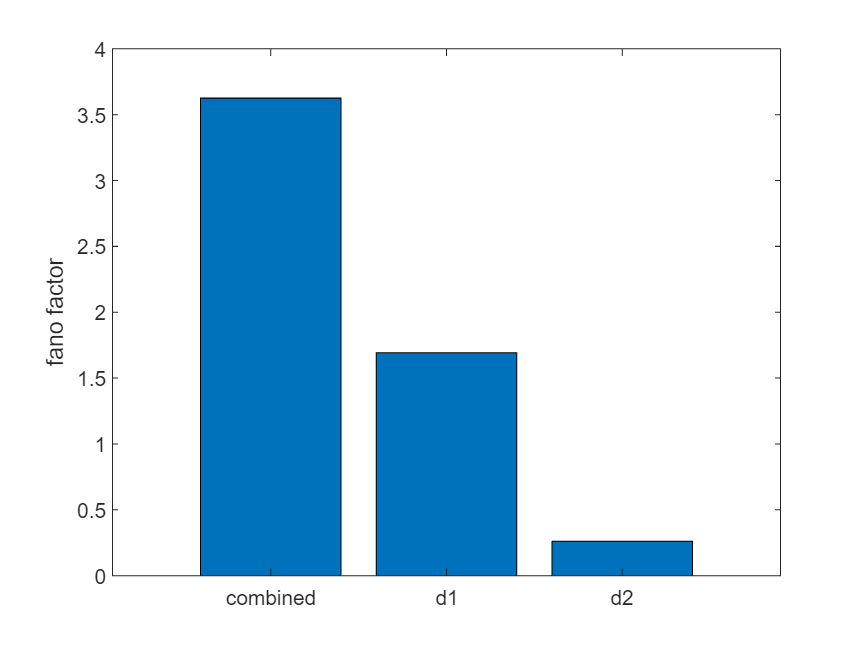


figure;bar(["combined", "d1", "d2"],[ff,ff_d1,ff_d2])
ylim([0 4])
ylabel('fano factor')

Calculate mean/var of acoustics 

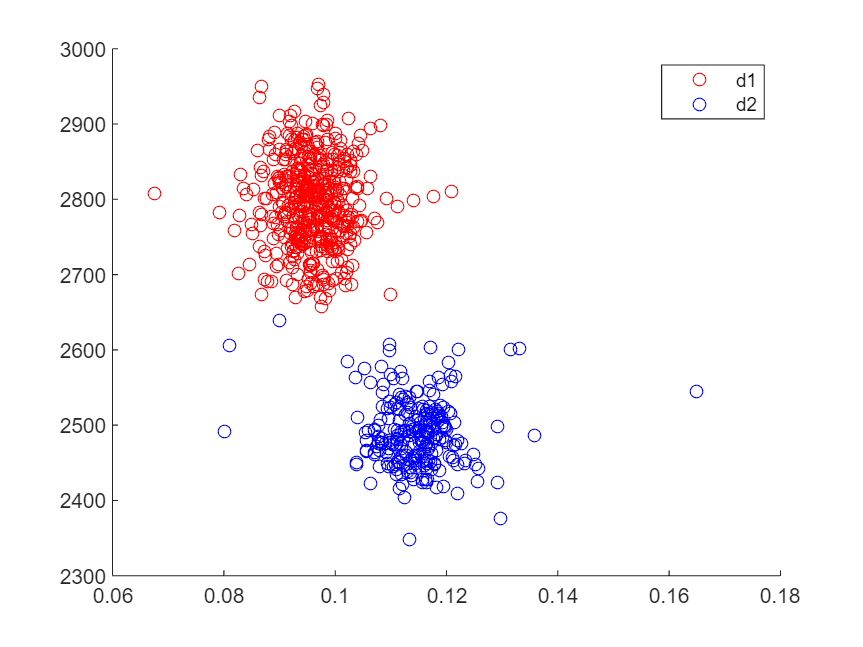

% split d1, d2 according to clusters
all_pitch = neuralcase.weighted_avg_pitch; 

d1_pitch = all_pitch(clusterIndices==1); 
d2_pitch = all_pitch(clusterIndices==2);
d1_durs = durs(clusterIndices==1);
d2_durs = durs(clusterIndices==2);

scatter(d1_durs,d1_pitch, 'red'); hold on
scatter(d2_durs,d2_pitch, "blue")
legend({'d1', 'd2'})

## Save d splitting results as separate compile_cases file

filename_d ='br177yw112_d_day86_ch6_premotor_200ms_spiketimes_acoustics_2024-02-17.mat';
filename_f = 'br177yw112_f_day86_ch6_premotor_200ms_spiketimes_acoustics_2024-02-17.mat';

save(filename_d, 'clusterIndices', 'centroids','acoustics','silh3', '-append')
save(filename_f, 'clusterIndices', 'centroids','acoustics','silh3', '-append')

## DAY 88

#### Plot distributions of pitch and syllable duration

clearvars
load('J:\MINI DATASET\br177yw112_day88_ch6\compile_cases\br177yw112_d_day88_ch6_premotor_40ms_spiketimes_acoustics_2023-12-02.mat')
f1 = clean_trials_table.pitch_wgt_avg;
durs = clean_trials_table.seq_ons_offs(:,2) - clean_trials_table.seq_ons_offs(:,1);

figure;histogram(f1); title('br177yw112: Day 88, syllable d'); xlabel('pitch')
figure;histogram(durs); title('br177yw112: Day 88, syllable d'); xlabel('duration (s)')

figure;scatter(durs,f1)
xlabel('syllable duration (sec)')
ylabel('fundamental frequency')

save('br177yw112_d_day88_ch6_premotor_40ms_spiketimes_acoustics_2024_01_08.mat','f1','durs')

Clustering using k-means

%create matrix of k-means
acoustics = table(f1, durs);
X(:,1) = f1; 
X(:,2) = durs;
rng('default')


% Perform k-means clustering using specified number of clusters (K value)
K = 2;
[clusterIndices,centroids] = kmeans(X,K);

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score] = pca(X);
clusterMeans = grpstats(score,clusterIndices,"mean");
h2 = gscatter(score(:,1),score(:,2),clusterIndices);
for i = 1:numel(h2)
    h2(i).DisplayName = strcat("Cluster",h2(i).DisplayName);
end
clear h2 i score
hold on
h2 = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h2.DisplayName = "ClusterMeans";
clear h2 clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");

% Matrix plot
figure
selectedCols = sort([2,1]);
[~,ax] = gplotmatrix(X(:,selectedCols),[],clusterIndices,[],[],[],[],"grpbars");
title("Comparison of Columns in Clustered Data");
clear K
clusterMeans = grpstats(X,clusterIndices,"mean");
hold(ax,"on");
for i = 1 : size(selectedCols,2)
  for j = 1 : size(selectedCols,2)
      if i ~= j  
          scatter(ax(j,i),clusterMeans(:,selectedCols(i)),clusterMeans(:,selectedCols(j)), ...
            50,"kx","LineWidth",1.5,"DisplayName","ClusterMeans");
          xlabel(ax(size(selectedCols,2),i),("Column" + selectedCols(i)));
          ylabel(ax(i,1),("Column" + selectedCols(i)));
      end
   end
end
clear ax clusterMeans i j selectedCols

% silhouette plot to measure how close each point in one cluster is to points in the neighboring clusters
[silh3,h] = silhouette(X,clusterIndices,'cityblock');
xlabel('Silhouette Value')
ylabel('Cluster')

% save k-means results
filename = 'br177yw112_d_day88_ch6_premotor_40ms_spiketimes_acoustics_2024_01_08.mat';
save(filename, 'clusterIndices', 'centroids','acoustics','silh3', '-append')

Calculate fano factor with combined and split 'd' distributions

allspikes = neuralcase.spiketrains; 
ntrials = length(allspikes);
onsets = neuralcase.syl_ons_offs(:,1);

preonset = 0.01;
postonset = 0.03;
motor_window = preonset + postonset;


motorWinOn = onsets - preonset;
motorWinOff = onsets + postonset; 
 % for each trial in curr case, caculate spike count, mean isi & mean ifr 
    for jj = 1:ntrials
        spk = allspikes{jj};
        spks_wn{jj,1} = spk(spk >= motorWinOn(jj) & spk <= motorWinOff(jj));
        n_spikes(jj,1) = length(spks_wn{jj}); %spk count

        if n_spikes(jj,1) > 1
            mean_isi_case(jj) = mean(diff(spks_wn{jj,1})); % mean isi
            mean_ifr_case(jj) = 1/mean_isi_case(jj); % mean ifr
        end
    end


ff = var(n_spikes)/ mean(n_spikes)

split 'd'

% split d1, d2
d1 = allspikes(clusterIndices==1); 
d2 = allspikes(clusterIndices==2);
ntrials_d1 = length(d1);
ntrials_d2 = length(d2);
onsets_d1 = onsets(clusterIndices ==1);
onsets_d2 = onsets(clusterIndices ==2);

preonset = 0.01;
postonset = 0.03;
motor_window = preonset + postonset;


motorWinOn_d1 = onsets_d1 - preonset;
motorWinOff_d1 = onsets_d1 + postonset; 
motorWinOn_d2 = onsets_d2 - preonset;
motorWinOff_d2 = onsets_d2 + postonset; 

clearvars n_spikes spks spks_wn 
 % for each trial in curr case, caculate spike count, mean isi & mean ifr 
    for j = 1:ntrials_d1
        spk = d1{j};
        spks_wn{j,1} = spk(spk >= motorWinOn_d1(j) & spk <= motorWinOff_d1(j));
        n_spikes(j,1) = length(spks_wn{j}); %spk count

        if n_spikes(j,1) > 1
            mean_isi_case(j) = mean(diff(spks_wn{j,1})); % mean isi
            mean_ifr_case(j) = 1/mean_isi_case(j); % mean ifr
        end
    end

ff_d1 = var(n_spikes)/ mean(n_spikes)

clearvars n_spikes spks spks_wn 
 % for each trial in curr case, caculate spike count, mean isi & mean ifr 
    for jj = 1:ntrials_d2
        spk = d2{jj};
        spks_wn{jj,1} = spk(spk >= motorWinOn_d2(jj) & spk <= motorWinOff_d2(jj));
        n_spikes(jj,1) = length(spks_wn{jj}); %spk count

        if n_spikes(jj,1) > 1
            mean_isi_case(jj) = mean(diff(spks_wn{jj,1})); % mean isi
            mean_ifr_case(jj) = 1/mean_isi_case(jj); % mean ifr
        end
    end

ff_d2 = var(n_spikes)/ mean(n_spikes)


## DAY 73

#### Plot distributions of pitch and syllable duration

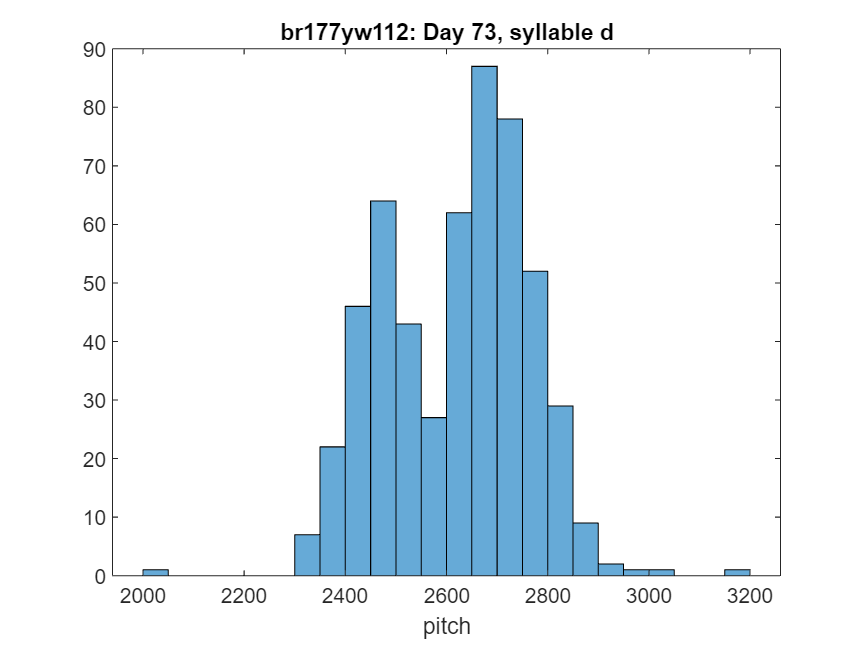

birdID = 'br177yw112';
neuronID = 'day73';
syl_or_seq = 'd';
neural_channel = 10;
pre_onset_time_s = 0.2;
filelist = 'batch_passing_ch10_clust3.txt';

% [neuralcase] = compile_case(birdID,neuronID,syl_or_seq,neural_channel,pre_onset_time_s,filelist)

load('J:\MINI DATASET\br177yw112_day73_ch10\compile_cases\br177yw112_d_day73_ch10_premotor_200ms_spiketimes_acoustics_2024-02-17.mat')
f1 = neuralcase.weighted_avg_pitch;
durs = neuralcase.syl_ons_offs(:,2) - neuralcase.syl_ons_offs(:,1);
recname = neuralcase.recfilename;

figure;histogram(f1); title('br177yw112: Day 73, syllable d'); xlabel('pitch')

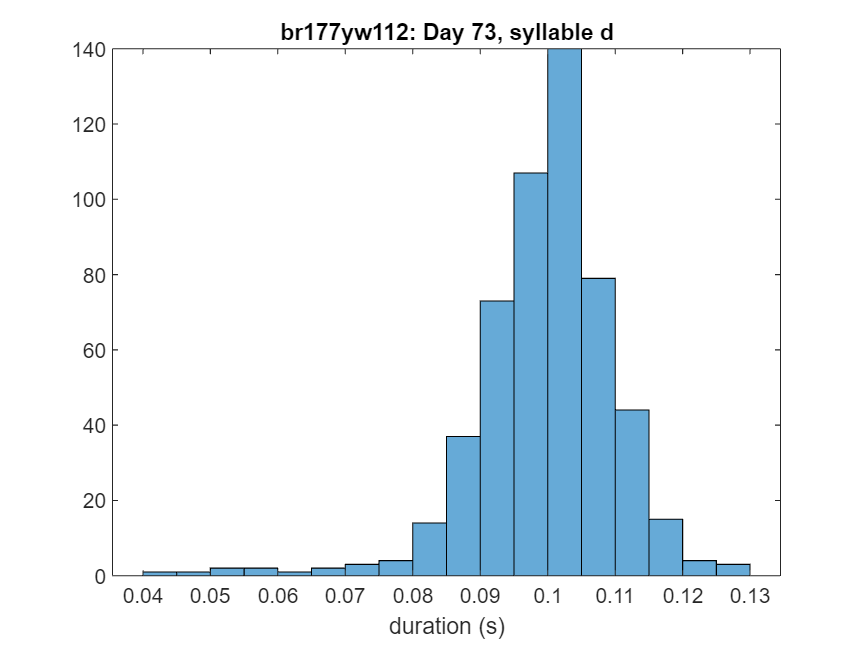

figure;histogram(durs); title('br177yw112: Day 73, syllable d'); xlabel('duration (s)')

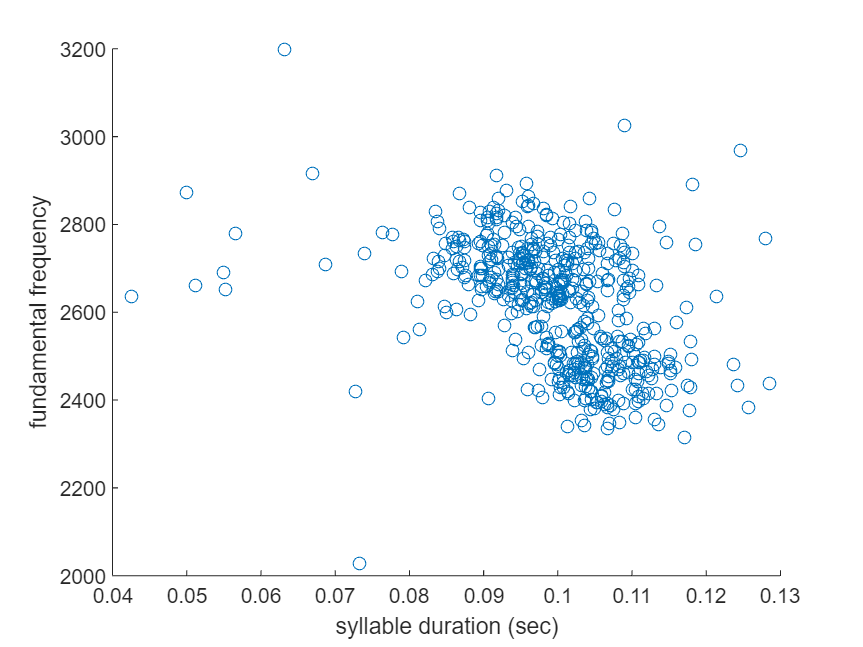


figure;scatter(durs,f1)
xlabel('syllable duration (sec)')
ylabel('fundamental frequency')

% find shortened syllable trials
short = durs > 0.14;
short_d_files = recname(short);
short_onsets = neuralcase.syl_ons_offs(short,1:2);

Cluster using k-means, assume 2 clusters

%create matrix of k-means
acoustics = table(f1, durs);
X(:,1) = f1; 
X(:,2) = durs;
rng('default')


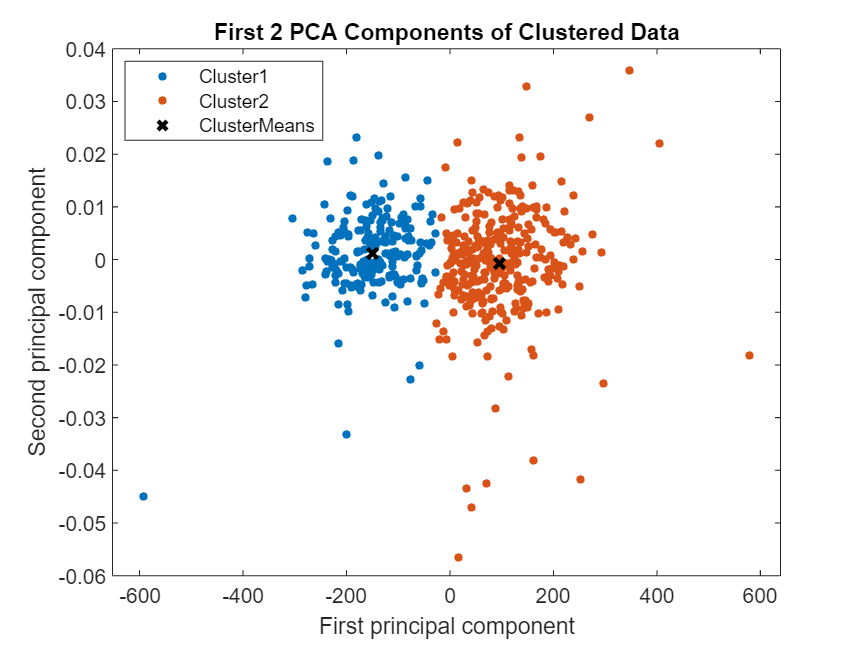

% Perform k-means clustering using specified number of clusters (K value)
K2 = 2;
[clusterIndices,centroids] = kmeans(X,K2);
clear K2

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score2] = pca(X);
clusterMeans2 = grpstats(score2,clusterIndices,"mean");
h3 = gscatter(score2(:,1),score2(:,2),clusterIndices);
for i2 = 1:numel(h3)
    h3(i2).DisplayName = strcat("Cluster",h3(i2).DisplayName);
end
clear h3 i2 score2
hold on
h3 = scatter(clusterMeans2(:,1),clusterMeans2(:,2),50,"kx","LineWidth",2);
hold off
h3.DisplayName = "ClusterMeans";
clear h3 clusterMeans2
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");

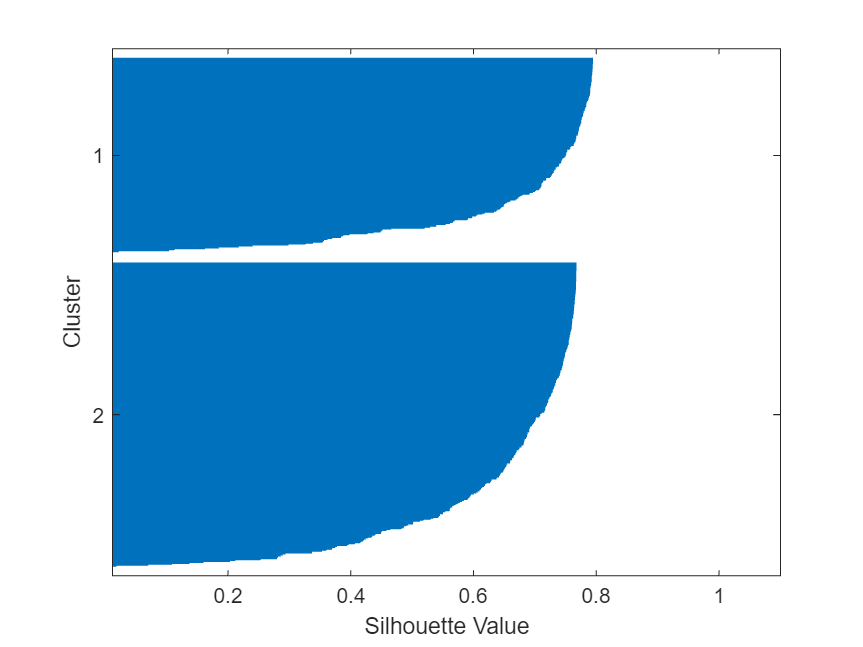


% silhouette plot to measure how close each point in one cluster is to points in the neighboring clusters
[silh3,h] = silhouette(X,clusterIndices,'cityblock');
xlabel('Silhouette Value')
ylabel('Cluster')


% save k-means results
filename = 'br177yw112_d_day73_ch10_premotor_200ms_spiketimes_acoustics_2024-02-17.mat';
save(filename, 'clusterIndices', 'centroids','acoustics','silh3', '-append')

Calculate fano factor with combined and split 'd' distributions

% all 'd', no split
allspikes = neuralcase.spiketrains; 
ntrials = length(allspikes);
onsets = neuralcase.syl_ons_offs(:,1);

preonset = 0.01;
postonset = 0.03;
motor_window = preonset + postonset;


motorWinOn = onsets - preonset;
motorWinOff = onsets + postonset; 
 % for each trial in curr case, caculate spike count, mean isi & mean ifr 
    for j = 1:ntrials
        spk = allspikes{j};
        spks_wn{j,1} = spk(spk >= motorWinOn(j) & spk <= motorWinOff(j));
        n_spikes(j,1) = length(spks_wn{j}); %spk count

        if n_spikes(j,1) > 1
            mean_isi_case(j) = mean(diff(spks_wn{j,1})); % mean isi
            mean_ifr_case(j) = 1/mean_isi_case(j); % mean ifr
        end
    end


ff = var(n_spikes)/ mean(n_spikes)

ff = 1.1275

split 'd'

% split d1, d2 according to clusters
d1 = allspikes(clusterIndices==1); 
d2 = allspikes(clusterIndices==2);
ntrials_d1 = length(d1);
ntrials_d2 = length(d2);
onsets_d1 = onsets(clusterIndices ==1);
onsets_d2 = onsets(clusterIndices ==2);

preonset = 0.01;
postonset = 0.03;
motor_window = preonset + postonset;


motorWinOn_d1 = onsets_d1 - preonset;
motorWinOff_d1 = onsets_d1 + postonset; 
motorWinOn_d2 = onsets_d2 - preonset;
motorWinOff_d2 = onsets_d2 + postonset; 

clearvars n_spikes spks spks_wn 
 % for each trial in curr case, caculate spike count, mean isi & mean ifr 
    for j = 1:ntrials_d1
        spk = d1{j};
        spks_wn{j,1} = spk(spk >= motorWinOn_d1(j) & spk <= motorWinOff_d1(j));
        n_spikes(j,1) = length(spks_wn{j}); %spk count

        if n_spikes(j,1) > 1
            mean_isi_case(j) = mean(diff(spks_wn{j,1})); % mean isi
            mean_ifr_case(j) = 1/mean_isi_case(j); % mean ifr
        end
    end

ff_d1 = var(n_spikes)/ mean(n_spikes)

ff_d1 = 1.6925


clearvars n_spikes spks spks_wn 
 % for each trial in curr case, caculate spike count, mean isi & mean ifr 
    for jj = 1:ntrials_d2
        spk = d2{jj};
        spks_wn{jj,1} = spk(spk >= motorWinOn_d2(jj) & spk <= motorWinOff_d2(jj));
        n_spikes(jj,1) = length(spks_wn{jj}); %spk count

        if n_spikes(jj,1) > 1
            mean_isi_case(jj) = mean(diff(spks_wn{jj,1})); % mean isi
            mean_ifr_case(jj) = 1/mean_isi_case(jj); % mean ifr
        end
    end

ff_d2 = var(n_spikes)/ mean(n_spikes)

ff_d2 = 0.2608


figure;bar({"combined","d2","d2"],[ff,ff_d1,ff_d2])

Error using bar
XData values must be unique.

ylim([1.0 1.2])
ylabel('fano factor')


Calculate mean/var of acoustics 

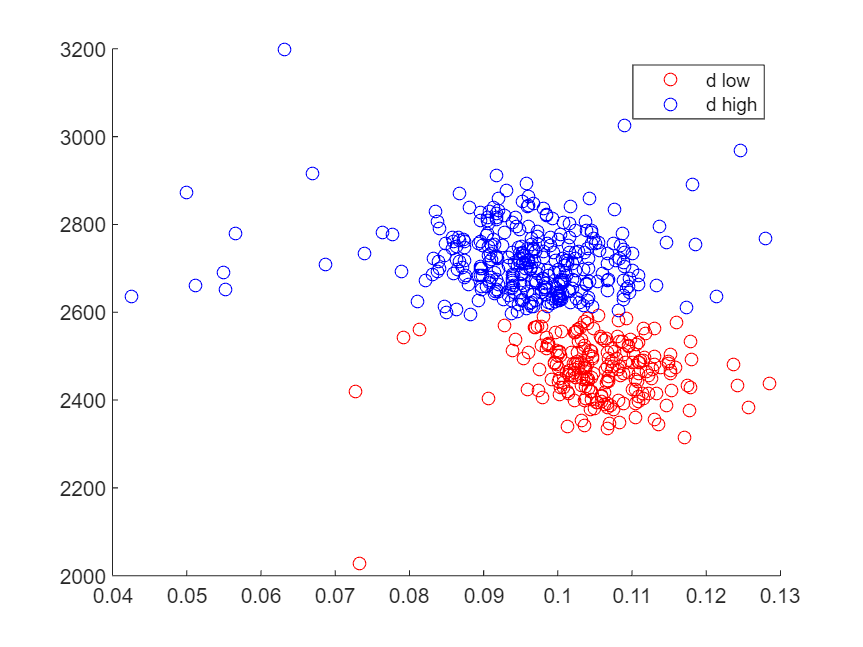

% split d1, d2 according to clusters
all_pitch = neuralcase.weighted_avg_pitch; 

d1_pitch = all_pitch(clusterIndices==1); 
d2_pitch = all_pitch(clusterIndices==2);
d1_durs = durs(clusterIndices==1);
d2_durs = durs(clusterIndices==2);

scatter(d1_durs,d1_pitch, 'red'); hold on
scatter(d2_durs,d2_pitch, "blue")
legend({'d low', 'd high'})

## DAY 62

#### Plot distributions of pitch and syllable duration

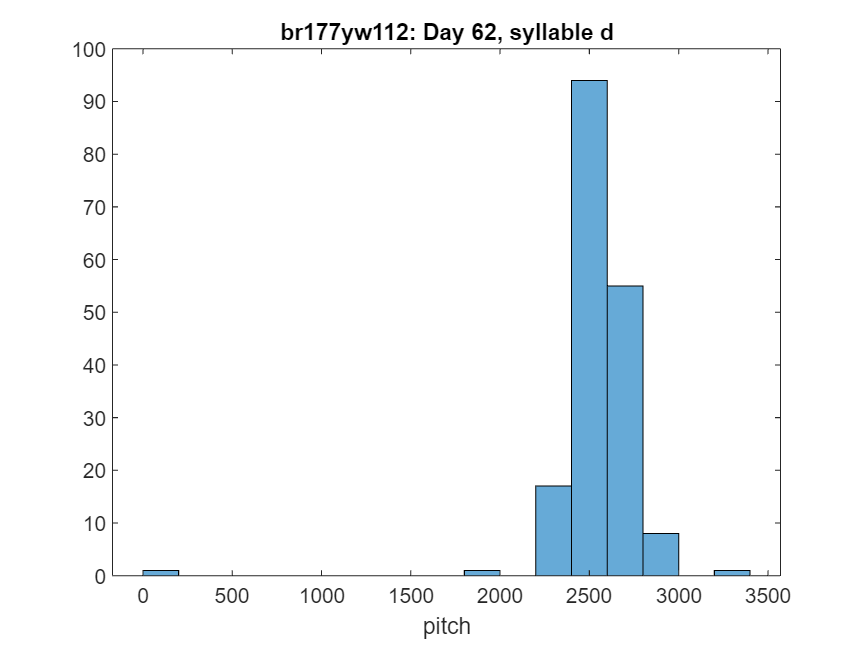

birdID = 'br177yw112';
neuronID = 'day62';
syl_or_seq = 'd';
neural_channel = 2;
pre_onset_time_s = 0.2;
filelist = 'batch_passed_files.txt';

% [neuralcase] = compile_case(birdID,neuronID,syl_or_seq,neural_channel,pre_onset_time_s,filelist)

load('J:\MINI DATASET\br177yw112_day62_ch2\compile_cases\br177yw112_d_day62_ch2_premotor_200ms_spiketimes_acoustics_2024-02-17.mat')
f1 = neuralcase.weighted_avg_pitch;
durs = neuralcase.syl_ons_offs(:,2) - neuralcase.syl_ons_offs(:,1);
recname = neuralcase.recfilename;

figure;histogram(f1); title('br177yw112: Day 62, syllable d'); xlabel('pitch')

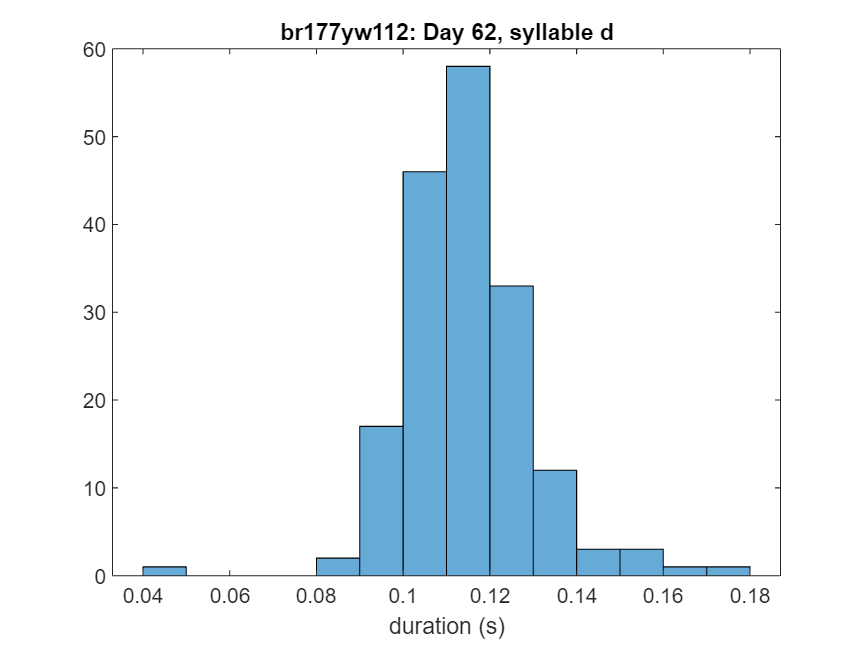

figure;histogram(durs); title('br177yw112: Day 62, syllable d'); xlabel('duration (s)')

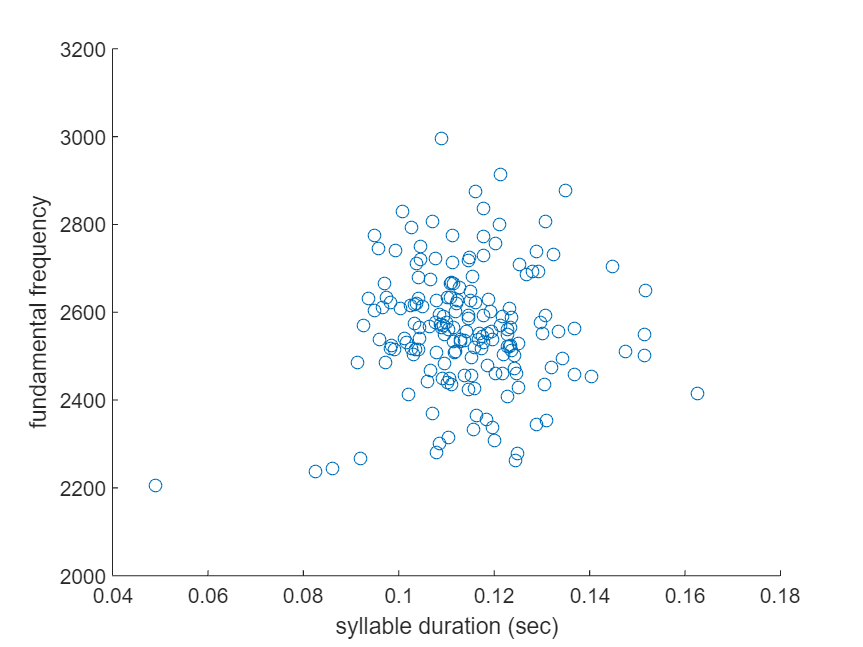


figure;scatter(durs,f1)
xlabel('syllable duration (sec)')
ylabel('fundamental frequency')
ylim([2000 3200])

## DAY 68

#### Plot distributions of pitch and syllable duration

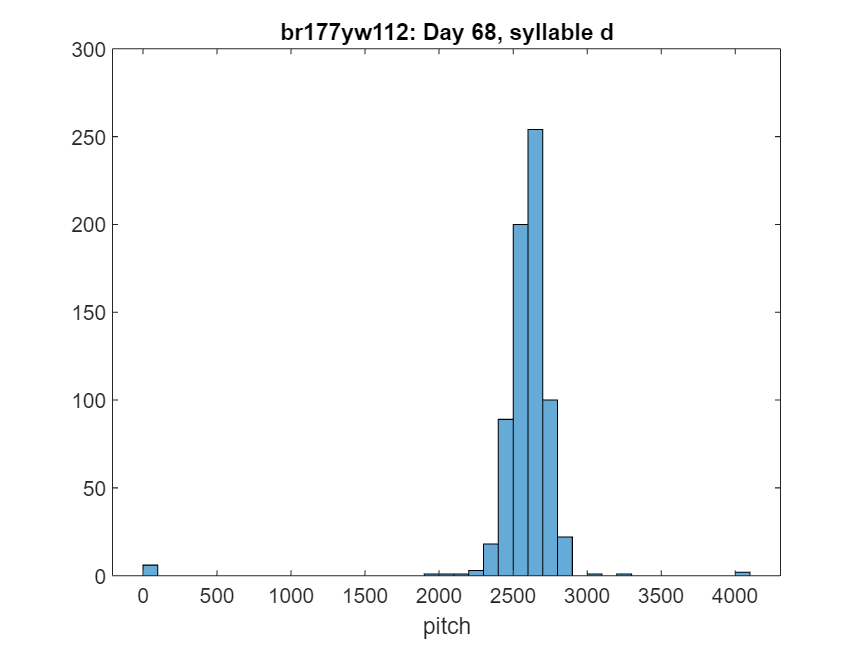

birdID = 'br177yw112';
neuronID = 'day62';
syl_or_seq = 'd';
neural_channel = 9;
pre_onset_time_s = 0.2;
filelist = 'batch_passed_ch9_clust3.txt';

% [neuralcase] = compile_case(birdID,neuronID,syl_or_seq,neural_channel,pre_onset_time_s,filelist)

load('J:\MINI DATASET\br177yw112_day68_ch9\1202-2216\compile_cases\br177yw112_d_day68_ch9_premotor_200ms_spiketimes_acoustics_2024-02-16.mat')
f1 = neuralcase.weighted_avg_pitch;
durs = neuralcase.syl_ons_offs(:,2) - neuralcase.syl_ons_offs(:,1);
recname = neuralcase.recfilename;

figure;histogram(f1); title('br177yw112: Day 68, syllable d'); xlabel('pitch')

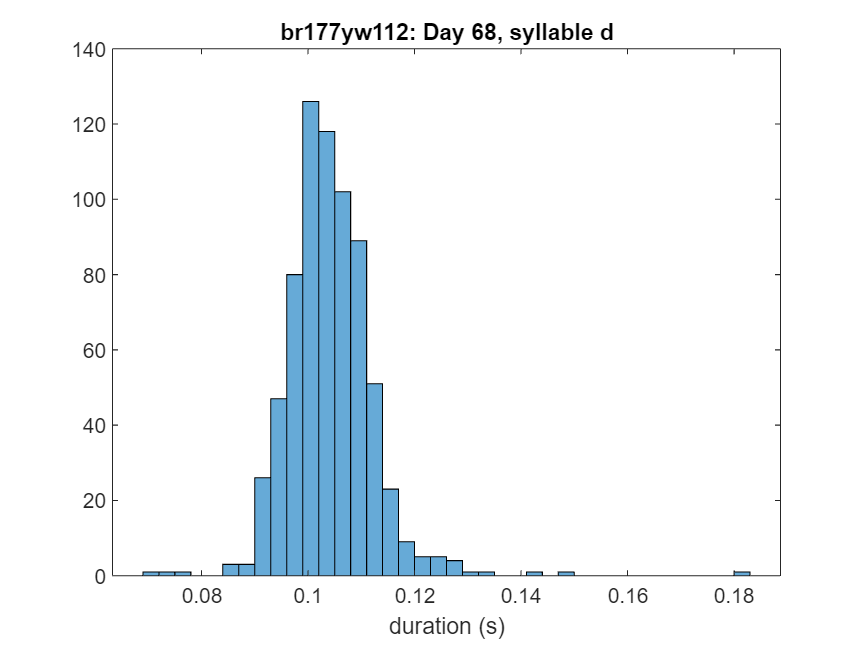

figure;histogram(durs); title('br177yw112: Day 68, syllable d'); xlabel('duration (s)')

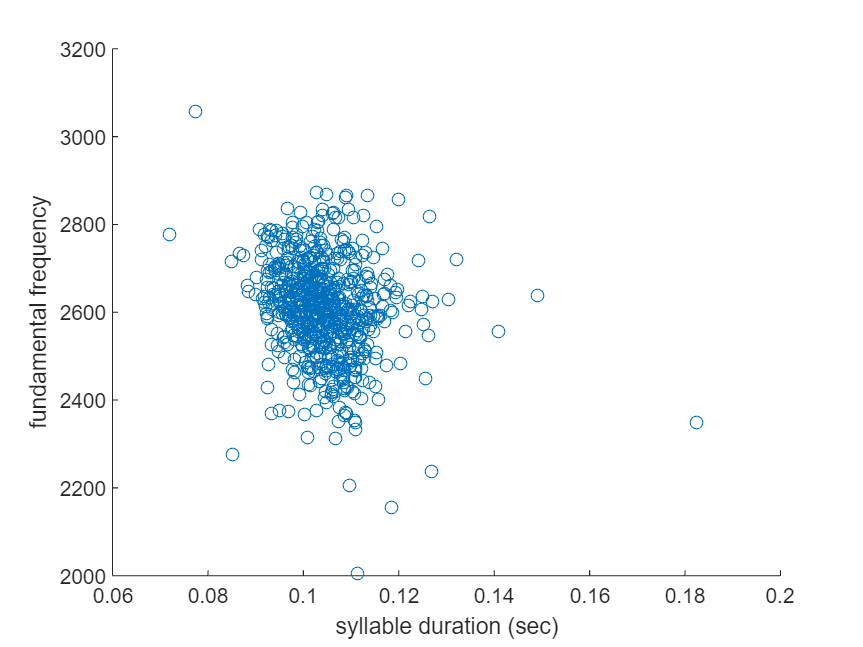


figure;scatter(durs,f1)
xlabel('syllable duration (sec)')
ylabel('fundamental frequency')
ylim([2000 3200])

Cluster using k-means, assume 2 clusters

%create matrix of k-means
acoustics = table(f1, durs);
X(:,1) = f1; 
X(:,2) = durs;
rng('default')


% Perform k-means clustering using specified number of clusters (K value)
K2 = 2;
[clusterIndices,centroids] = kmeans(X,K2);
clear K2

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score2] = pca(X);
clusterMeans2 = grpstats(score2,clusterIndices,"mean");
h3 = gscatter(score2(:,1),score2(:,2),clusterIndices);
for i2 = 1:numel(h3)
    h3(i2).DisplayName = strcat("Cluster",h3(i2).DisplayName);
end
clear h3 i2 score2
hold on
h3 = scatter(clusterMeans2(:,1),clusterMeans2(:,2),50,"kx","LineWidth",2);
hold off
h3.DisplayName = "ClusterMeans";
clear h3 clusterMeans2
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");

% silhouette plot to measure how close each point in one cluster is to points in the neighboring clusters
[silh3,h] = silhouette(X,clusterIndices,'cityblock');
xlabel('Silhouette Value')
ylabel('Cluster')

% save k-means results
filename = 'br177yw112_d_day73_ch10_premotor_200ms_spiketimes_acoustics_2024-02-17.mat';
save(filename, 'clusterIndices', 'centroids','acoustics','silh3', '-append')

Calculate fano factor with combined and split 'd' distributions

% all 'd', no split
allspikes = neuralcase.spiketrains; 
ntrials = length(allspikes);
onsets = neuralcase.syl_ons_offs(:,1);

preonset = 0.01;
postonset = 0.03;
motor_window = preonset + postonset;


motorWinOn = onsets - preonset;
motorWinOff = onsets + postonset; 
 % for each trial in curr case, caculate spike count, mean isi & mean ifr 
    for j = 1:ntrials
        spk = allspikes{j};
        spks_wn{j,1} = spk(spk >= motorWinOn(j) & spk <= motorWinOff(j));
        n_spikes(j,1) = length(spks_wn{j}); %spk count

        if n_spikes(j,1) > 1
            mean_isi_case(j) = mean(diff(spks_wn{j,1})); % mean isi
            mean_ifr_case(j) = 1/mean_isi_case(j); % mean ifr
        end
    end


ff = var(n_spikes)/ mean(n_spikes)


split 'd'

% split d1, d2 according to clusters
d1 = allspikes(clusterIndices==1); 
d2 = allspikes(clusterIndices==2);
ntrials_d1 = length(d1);
ntrials_d2 = length(d2);
onsets_d1 = onsets(clusterIndices ==1);
onsets_d2 = onsets(clusterIndices ==2);

preonset = 0.01;
postonset = 0.03;
motor_window = preonset + postonset;


motorWinOn_d1 = onsets_d1 - preonset;
motorWinOff_d1 = onsets_d1 + postonset; 
motorWinOn_d2 = onsets_d2 - preonset;
motorWinOff_d2 = onsets_d2 + postonset; 

clearvars n_spikes spks spks_wn 
 % for each trial in curr case, caculate spike count, mean isi & mean ifr 
    for j = 1:ntrials_d1
        spk = d1{j};
        spks_wn{j,1} = spk(spk >= motorWinOn_d1(j) & spk <= motorWinOff_d1(j));
        n_spikes(j,1) = length(spks_wn{j}); %spk count

        if n_spikes(j,1) > 1
            mean_isi_case(j) = mean(diff(spks_wn{j,1})); % mean isi
            mean_ifr_case(j) = 1/mean_isi_case(j); % mean ifr
        end
    end

ff_d1 = var(n_spikes)/ mean(n_spikes)

clearvars n_spikes spks spks_wn 
 % for each trial in curr case, caculate spike count, mean isi & mean ifr 
    for jj = 1:ntrials_d2
        spk = d2{jj};
        spks_wn{jj,1} = spk(spk >= motorWinOn_d2(jj) & spk <= motorWinOff_d2(jj));
        n_spikes(jj,1) = length(spks_wn{jj}); %spk count

        if n_spikes(jj,1) > 1
            mean_isi_case(jj) = mean(diff(spks_wn{jj,1})); % mean isi
            mean_ifr_case(jj) = 1/mean_isi_case(jj); % mean ifr
        end
    end

ff_d2 = var(n_spikes)/ mean(n_spikes)

figure;bar({"combined","d2","d2"],[ff,ff_d1,ff_d2])
ylim([1.0 1.2])
ylabel('fano factor')


Calculate mean/var of acoustics 

% split d1, d2 according to clusters
all_pitch = neuralcase.weighted_avg_pitch; 

d1_pitch = all_pitch(clusterIndices==1); 
d2_pitch = all_pitch(clusterIndices==2);
d1_durs = durs(clusterIndices==1);
d2_durs = durs(clusterIndices==2);

scatter(d1_durs,d1_pitch, 'red'); hold on
scatter(d2_durs,d2_pitch, "blue")
legend({'d low', 'd high'})